% Board Size (Note that the board size will be one less than the numbers
% you choose)
rows = 12;
columns = 16;

boundaryX = columns - 1;
boundaryY = rows - 1;

% Treasure location
treasureX = randi(boundaryX);
treasureY = randi(boundaryY); 

% Creates the blank map
gameMap = zeros(rows, columns);
gameMap(:) = NaN;

% Creates the colored in map
xCoords = 1:columns;
yCoords = 1:rows;
solutionMap = abs(treasureX - xCoords) + abs(treasureY - yCoords)';

% Set the treasure to a high value so it appears correctly
solutionMap(treasureY,treasureX) = rows+columns+1;

% The colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0];

% Number of guesses the player has made
numGuesses = 0;

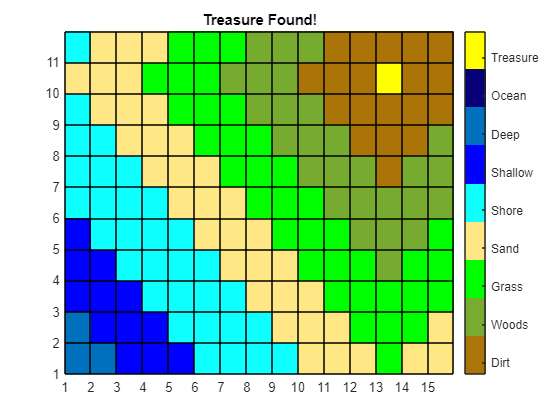

%Board Setup
p = pcolor(gameMap);
hold on
xticks(1:1:boundaryX);
yticks(1:1:boundaryY);

colormap(cmap);
clim([0 rows+columns+1]);

c = colorbar;
c.Ticks = 1:(rows+columns+1)/9:(rows+columns+1);
c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'};

title("Find the Treasure!")

%Play Game
 

if(numGuesses ~= 0)
    guessX = 13;
    guessY = 10;

    %Run function to check guesses
    playGame(treasureX,treasureY,gameMap,solutionMap,guessX,guessY,numGuesses)
    numGuesses = numGuesses + 1;
else
    %Increments the Guess Numbers to start the game
    numGuesses = numGuesses + 1;
end

function playGame(treasureX,treasureY,gameMap,solutionMap,guessX,guessY,numGuesses)
    % If the treasure has been found
    if(guessX == treasureX)&&(guessY == treasureY)
        % Display the finalMap
        pcolor(solutionMap);

        % Change the title to "Treasure Found!"
        title("Treasure Found!");

    % If the treasure has not been found
    else
        % Set the guessed location in map equal to the guessed location in
        % finalMap
        gameMap(guessY,guessX) = solutionMap(guessY,guessX);

        % Display the updated map
        pcolor(gameMap);
        
        % Tell the player how far they are from the
        % treasure, and how many guesses they've taken so far
        help = "You are " + string(solutionMap(guessY,guessX)) + " away from the treasure.";
        guess = "Guess: " + numGuesses;
        disp(help);
        disp(guess);
        disp("Guess again!");
    end
end